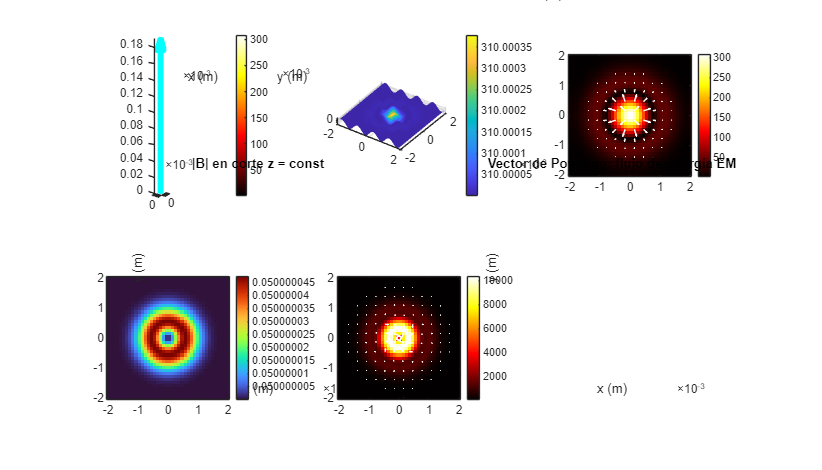

clear; clc; close all;

%% 1. Malla espacial
N = 40;                     
x = linspace(-2e-3, 2e-3, N);
y = linspace(-2e-3, 2e-3, N);
z = linspace(0, 5e-3, N);

% ndgrid para la física
[X, Y, Z] = ndgrid(x, y, z);
r = sqrt(X.^2 + Y.^2);

dx = x(2)-x(1);
dy = y(2)-y(1);
dz = z(2)-z(1);

%% 2. Parámetros del plasma
v0      = 2e3;      % m/s
sigma_v = 0.7e-3;   % m
B0      = 0.05;     % T
B1      = 0.2;      % T/m
sigma_B = 0.8e-3;   % m

eta = 1e-3;         % ohm·m
mu0 = 4e-7*pi;

% Velocidad axial
vz = v0 * exp(-(r.^2)/(sigma_v^2));
vx = zeros(size(vz));
vy = zeros(size(vz));

% Campo magnético: Bz + componente toroidal
Bz = B0 * ones(size(vz));
Btheta = B1 * r .* exp(-(r.^2)/(sigma_B^2));
theta = atan2(Y, X);
Bx = -Btheta .* sin(theta);
By =  Btheta .* cos(theta);

%% 3. Corriente J = (1/mu0) curl B (diferencias centradas)
dBz_dy = (circshift(Bz, [0 -1 0]) - circshift(Bz, [0 1 0]))/(2*dy);
dBy_dz = (circshift(By, [0 0 -1]) - circshift(By, [0 0 1]))/(2*dz);
dBx_dz = (circshift(Bx, [0 0 -1]) - circshift(Bx, [0 0 1]))/(2*dz);
dBz_dx = (circshift(Bz, [-1 0 0]) - circshift(Bz, [1 0 0]))/(2*dx);
dBy_dx = (circshift(By, [-1 0 0]) - circshift(By, [1 0 0]))/(2*dx);
dBx_dy = (circshift(Bx, [0 -1 0]) - circshift(Bx, [0 1 0]))/(2*dy);

Jx = (dBz_dy - dBy_dz)/mu0;
Jy = (dBx_dz - dBz_dx)/mu0;
Jz = (dBy_dx - dBx_dy)/mu0;

%% 4. Campo eléctrico: E = -v x B + eta J
vxB_x = vy.*Bz - vz.*By;
vxB_y = vz.*Bx - vx.*Bz;
vxB_z = vx.*By - vy.*Bx;

Ex = -vxB_x + eta.*Jx;
Ey = -vxB_y + eta.*Jy;
Ez = -vxB_z + eta.*Jz;

Emag = sqrt(Ex.^2 + Ey.^2 + Ez.^2);
Bmag = sqrt(Bx.^2 + By.^2 + Bz.^2);

%% 4.5 Vector de Poynting S = (1/mu0) * (E x B)
Sx = (Ey .* Bz - Ez .* By) / mu0;
Sy = (Ez .* Bx - Ex .* Bz) / mu0;
Sz = (Ex .* By - Ey .* Bx) / mu0;

Smag = sqrt(Sx.^2 + Sy.^2 + Sz.^2);

Sx_mg   = permute(Sx,   [2 1 3]);
Sy_mg   = permute(Sy,   [2 1 3]);
Sz_mg   = permute(Sz,   [2 1 3]);
Smag_mg = permute(Smag, [2 1 3]);

%% 5. Tejido neuronal en z=0
k0 = 1;   % índice z=0 
[TX, TY] = ndgrid(x, y);
TZ = 0.2e-3 * sin(4*pi*TX/max(x)) .* cos(4*pi*TY/max(y));

sigma_t = 0.5;  % S/m
Q0 = sigma_t * squeeze(Emag(:,:,k0)).^2;

rho_t = 1050;
c_t   = 3600;
k_t   = 0.5;
alpha = k_t/(rho_t*c_t);

dt    = 0.03;
steps = 60;

T = 310 * ones(size(Q0));   % 37 ºC
dx2 = dx^2;
dy2 = dy^2;

lap2d = @(F) (circshift(F,[-1 0]) - 2*F + circshift(F,[1 0]))/dx2 + ...
             (circshift(F,[0 -1]) - 2*F + circshift(F,[0 1]))/dy2;

%% --- Conversión ndgrid → meshgrid para visualización ---
[Xm, Ym, Zm] = meshgrid(x, y, z);
Emag_mg = permute(Emag, [2 1 3]);   % clave para isosurface/isonormals
Ex_mg   = permute(Ex,   [2 1 3]);
Ey_mg   = permute(Ey,   [2 1 3]);
Ez_mg   = permute(Ez,   [2 1 3]);
Bmag_mg = permute(Bmag,[2 1 3]);

%% 6. Figura y animación
figure('Color','w');
set(gcf,'Position',[50 50 1400 800]);

kMid = round(N*0.25);   % corte donde el plasma es fuerte

for n = 1:steps
    % Difusión + fuente
    L = lap2d(T);
    T = T + alpha*L*dt + (Q0/(rho_t*c_t))*dt;

    clf;

    %% (1,1) Chorro de plasma: isosuperficie de |E| + B 3D
    subplot(2,3,1);

    level = max(Emag(:))*0.4;

    p = patch(isosurface(Xm, Ym, Zm, Emag_mg, level));
    isonormals(Xm, Ym, Zm, Emag_mg, p);

    set(p,'FaceColor',[0.9 0.4 0.1], ...
          'EdgeColor','none', ...
          'FaceAlpha',0.4);

    hold on;
    axis equal
    camlight; lighting gouraud;

    xslice = 0;
    yslice = 0;
    zslice = [1e-3 3e-3];
    slice(Xm, Ym, Zm, Emag_mg, xslice, yslice, zslice);
    shading interp;

    colormap(subplot(2,3,1), hot);
    colorbar;
    axis equal; axis tight;
    xlabel('x (m)'); ylabel('y (m)'); zlabel('z (m)');
    title('|E| chorro plasma');
    view(35,25);
    camlight; lighting gouraud;

    % Campo magnético 3D
    hold on;
    stepQ = 4;
    Xq  = Xm(1:stepQ:end,1:stepQ:end,1:stepQ:end);
    Yq  = Ym(1:stepQ:end,1:stepQ:end,1:stepQ:end);
    Zq  = Zm(1:stepQ:end,1:stepQ:end,1:stepQ:end);

    Bxq = permute(Bx, [2 1 3]);
    Byq = permute(By, [2 1 3]);
    Bzq = permute(Bz, [2 1 3]);

    Bxq = Bxq(1:stepQ:end,1:stepQ:end,1:stepQ:end);
    Byq = Byq(1:stepQ:end,1:stepQ:end,1:stepQ:end);
    Bzq = Bzq(1:stepQ:end,1:stepQ:end,1:stepQ:end);

    quiver3(Xq, Yq, Zq, Bxq, Byq, Bzq, 5e2, 'c');

    %% (1,2) Tejido deformado por temperatura
    subplot(2,3,2);
    dT = T - 310;
    Zwarp = TZ + 5e-5 * dT;

    surf(TX, TY, Zwarp, T, 'EdgeColor','none');
    axis equal; axis tight;
    xlabel('x (m)'); ylabel('y (m)'); zlabel('z (m)');
    title(sprintf('Tejido neuronal, T (K), paso %d', n));
    colormap(subplot(2,3,2),'parula');
    colorbar;
    view(35,35);

    %% (1,3) Campo eléctrico en corte z = const
    subplot(2,3,3);

    Ex_slice = Ex_mg(:,:,kMid);
    Ey_slice = Ey_mg(:,:,kMid);
    Em_slice = Emag_mg(:,:,kMid);

    Xs = Xm(:,:,kMid);
    Ys = Ym(:,:,kMid);

    imagesc(x, y, Em_slice', [min(Em_slice(:)) max(Em_slice(:))]);
    axis xy;
    hold on;

    colormap(subplot(2,3,3), hot);
    colorbar;

    Emax = max(Em_slice(:));
    stepE = 3;

    quiver( Xs(1:stepE:end,1:stepE:end), ...
            Ys(1:stepE:end,1:stepE:end), ...
            Ex_slice(1:stepE:end,1:stepE:end)/Emax, ...
            Ey_slice(1:stepE:end,1:stepE:end)/Emax, ...
            0.6, 'w', 'LineWidth', 1.2);

    axis equal; axis tight;
    xlabel('x (m)'); ylabel('y (m)');
    title('Campo eléctrico en corte z = const');

    %% (2,1) Magnitud de B en corte z = const
    subplot(2,3,4);
    B_slice = Bmag_mg(:,:,kMid);
    imagesc(x, y, B_slice', [min(B_slice(:)) max(B_slice(:))]);
    axis xy;
    colormap(subplot(2,3,4), turbo);
    colorbar;
    axis equal; axis tight;
    xlabel('x (m)'); ylabel('y (m)');
    title('|B| en corte z = const');

    %% (2,2) Vector de Poynting en corte z = const
    subplot(2,3,5);

    S_slice  = Smag_mg(:,:,kMid);
    Sx_slice = Sx_mg(:,:,kMid);
    Sy_slice = Sy_mg(:,:,kMid);

    imagesc(x, y, S_slice', [min(S_slice(:)) max(S_slice(:))]);
    axis xy;
    hold on;

    colormap(subplot(2,3,5), hot);
    colorbar;

    Smax = max(S_slice(:));
    stepS = 3;

    quiver( Xs(1:stepS:end,1:stepS:end), ...
            Ys(1:stepS:end,1:stepS:end), ...
            Sx_slice(1:stepS:end,1:stepS:end)/Smax, ...
            Sy_slice(1:stepS:end,1:stepS:end)/Smax, ...
            0.6, 'w', 'LineWidth', 1.2);

    axis equal; axis tight;
    xlabel('x (m)'); ylabel('y (m)');
    title('Vector de Poynting: flujo de energía EM');

    drawnow;
end

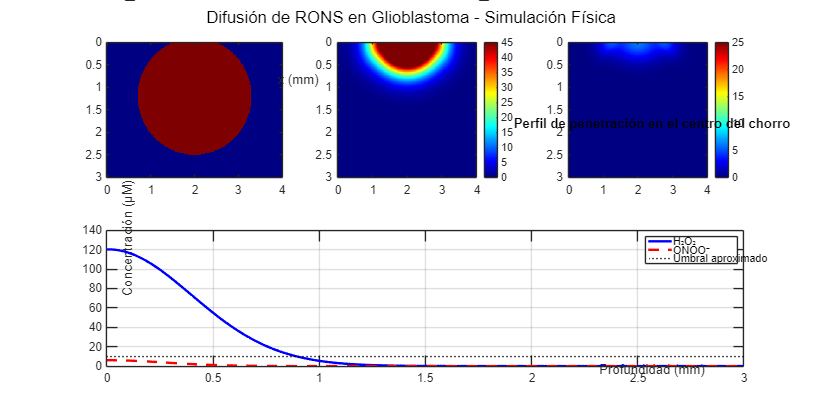

Simulación completada. ¡Geometría de glioblastoma más realista incluida!


%% Simulación Avanzada: Difusión de RONS en Glioblastoma Realista
% Ingeniería Física y Matemática - Aplicación de Plasma Atmosférico Frío (CAP)
clear; close all; clc;

%% Parámetros físicos y geométricos
Lx = 4e-3;      % Ancho del dominio [m] = 4 mm
Ly = 3e-3;      % Profundidad [m] = 3 mm
Nx = 300;
Ny = 225;
dx = Lx/(Nx-1);
dy = Ly/(Ny-1);
x = linspace(0, Lx, Nx);
y = linspace(0, Ly, Ny);

% Coeficientes de difusión (valores realistas)
D_h2o2  = 2.5e-9;   % m²/s para H₂O₂ en tejido cerebral
D_onoo  = 1.2e-9;   % m²/s para peroxinitrito / RONS corta vida

% Tiempos de simulación
t_exp   = 60;       % Tiempo de exposición al plasma [s]
t_max   = 300;      % Tiempo total [s]
dt      = 0.05;     % Paso de tiempo [s]
Nt      = round(t_max/dt);

%% Creación de geometría realista del glioblastoma
% Tumor irregular: núcleo + borde infiltrativo
[X, Y] = meshgrid(x, y);
tumor_core = ((X - 2e-3).^2 + (Y - 1.2e-3).^2) < (0.8e-3)^2;           % Núcleo central
tumor_border = ((X - 2e-3).^2 + (Y - 1.2e-3).^2) < (1.3e-3)^2 & ~tumor_core;
tumor_mask = tumor_core | tumor_border;

% Tasa de consumo (más alta en tumor)
k_h2o2  = 0.008 * tumor_mask + 0.002 * (~tumor_mask);   % 1/s
k_onoo  = 0.025 * tumor_mask + 0.005 * (~tumor_mask);   % más reactivo

%% Inicialización de concentraciones
C_h2o2 = zeros(Ny, Nx);
C_onoo = zeros(Ny, Nx);

%% Fuente del chorro de plasma (gaussiana para mayor realismo)
jet_center_x = Lx/2;
sigma_jet = 0.35e-3;
source_profile = exp(-((x - jet_center_x).^2)/(2*sigma_jet^2));

%% Simulación con método de diferencias finitas
figure('Position', [50 50 1400 700], 'Color', 'white');

for n = 1:Nt
    t = n * dt;
    
    % Aplicar fuente durante el tiempo de exposición
    if t < t_exp
        source_h2o2 = 1.8e-3 * source_profile;
        source_onoo = 0.9e-3 * source_profile;
        C_h2o2(1, :) = C_h2o2(1, :) + source_h2o2 * dt;   % superficie superior
        C_onoo(1, :) = C_onoo(1, :) + source_onoo * dt;
    end
    
    % Laplaciano (difusión)
    Lap_h2o2 = del2(C_h2o2, dx, dy);
    Lap_onoo = del2(C_onoo, dx, dy);
    
    % Actualización (difusión + reacción)
    C_h2o2 = C_h2o2 + dt * (D_h2o2 * Lap_h2o2 - k_h2o2 .* C_h2o2);
    C_onoo = C_onoo + dt * (D_onoo * Lap_onoo - k_onoo .* C_onoo);
    
    % Condiciones de contorno Neumann (sin flujo)
    C_h2o2([1 end], :) = C_h2o2([2 end-1], :);
    C_h2o2(:, [1 end]) = C_h2o2(:, [2 end-1]);
    C_onoo([1 end], :) = C_onoo([2 end-1], :);
    C_onoo(:, [1 end]) = C_onoo(:, [2 end-1]);
    
    % Visualización cada cierto intervalo
    if mod(n, round(Nt/15)) == 0 || n == 1 || n == Nt
        clf;
        
        subplot(2,3,1);
        imagesc(x*1e3, y*1e3, tumor_mask); colormap gray;
        title('Geometría del Glioblastoma');
        xlabel('x (mm)'); ylabel('Profundidad (mm)');
        set(gca,'YDir','reverse');
        
        subplot(2,3,2);
        imagesc(x*1e3, y*1e3, C_h2o2*1e6, [0 45]);
        colorbar; colormap jet;
        title(sprintf('H₂O₂ (µM) - t = %.0f s', t));
        xlabel('x (mm)'); ylabel('Profundidad (mm)');
        set(gca,'YDir','reverse');
        
        subplot(2,3,3);
        imagesc(x*1e3, y*1e3, C_onoo*1e6, [0 25]);
        colorbar; colormap jet;
        title(sprintf('ONOO⁻ / RONS corto (µM) - t = %.0f s', t));
        xlabel('x (mm)'); ylabel('Profundidad (mm)');
        set(gca,'YDir','reverse');
        
        subplot(2,3,4:6);
        idx_center = round(Nx/2);
        plot(y*1e3, C_h2o2(:,idx_center)*1e6, 'b-', 'LineWidth', 2); hold on;
        plot(y*1e3, C_onoo(:,idx_center)*1e6, 'r--', 'LineWidth', 2);
        yline(10, 'k:'); % umbral aproximado de efecto biológico
        xlabel('Profundidad (mm)'); ylabel('Concentración (µM)');
        legend('H₂O₂', 'ONOO⁻', 'Umbral aproximado');
        title('Perfil de penetración en el centro del chorro');
        grid on;
        
        sgtitle('Difusión de RONS en Glioblastoma - Simulación Física', 'FontSize', 14);
        drawnow;
        
        % Opcional: guardar frames para vídeo o pack de imágenes
        % frame = getframe(gcf); imwrite(frame.cdata, sprintf('RONS_frame_%03d.png', n));
    end
end

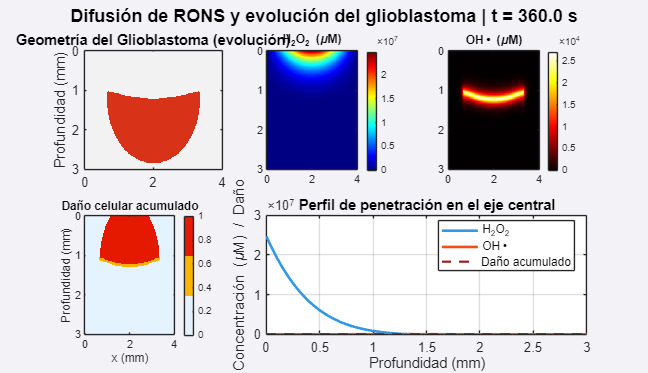

%% Simulación estable de difusión de RONS + reacción + evolución tumoral
clear; close all; clc;

%% Parámetros del dominio
Lx = 4e-3; Ly = 3e-3;
Nx = 280; Ny = 210;
dx = Lx/(Nx-1); dy = Ly/(Ny-1);
x = linspace(0, Lx, Nx);
y = linspace(0, Ly, Ny);
[X, Y] = meshgrid(x, y);

%% Coeficientes de difusión
D_h2o2 = 2.6e-9; % m^2/s
D_oh   = 0.8e-9; % m^2/s

%% Tiempo
t_exp = 60;   % duración de exposición al plasma
t_max = 360;

% Paso temporal estable para esquema explícito 2D
Dmax = max(D_h2o2, D_oh);
dt_stable = 0.24 * min(dx^2, dy^2) / Dmax; 
dt = min(0.01, dt_stable);                 
Nt = round(t_max/dt);

%% Geometría del glioblastoma
tumor_core = ((X - 2e-3).^2/(0.85e-3)^2 + (Y - 1.25e-3).^2/(1.1e-3)^2) < 1;
tumor_border = ((X - 2e-3).^2/(1.35e-3)^2 + (Y - 1.25e-3).^2/(1.6e-3)^2) < 1 & ~tumor_core;
tumor_mask = tumor_core | tumor_border;

damage = zeros(Ny, Nx);

%% Concentraciones
C_h2o2 = zeros(Ny, Nx);
C_oh   = zeros(Ny, Nx);

%% Fuente del chorro de plasma (gaussiana en superficie y=0)
jet_center = Lx/2;
sigma_jet = 0.40e-3;
source = exp(-((x - jet_center).^2)/(2*sigma_jet^2));

% Intensidad de inyección superficial
source_h2o2 = 2.1e-3; % unidades del modelo
source_oh   = 0.0;    % inyección de OH

%% Figura
figure('Position', [40 40 1480 850], 'Color', [0.95 0.95 0.97]);

%% Bucle temporal
save_every = max(1, round(Nt/8));

% --- AÑADIMOS 2–3 tiempos extra que queremos ver explícitamente ---
% Por ejemplo: 300 s, 400 s, 500 s (aunque t_max=360, pondré dos dentro)
times_extra = [300, 330, 360];   % 2 o 3 instantes posteriores que te interesan

for n = 1:Nt
    t = n*dt;

    % Inyección en la superficie superior durante la exposición
    if t < t_exp
        C_h2o2(1,:) = C_h2o2(1,:) + source_h2o2 * source * dt;
        C_oh(1,:)   = C_oh(1,:)   + source_oh   * source * dt;
    end

    % Laplacianos
    Lap_h2o2 = del2(C_h2o2, dx, dy);
    Lap_oh   = del2(C_oh,   dx, dy);

    % Consumo
    k_cons_h2o2 = 0.012 * tumor_mask + 0.003 * (~tumor_mask);
    k_cons_oh   = 0.17  * tumor_mask + 0.04  * (~tumor_mask);

    % Conversión H2O2 -> OH dentro del tumor
    reaction_rate = 0.038 * C_h2o2 .* tumor_mask;

    % Actualización explícita estable
    C_h2o2_new = C_h2o2 + dt * (D_h2o2 * Lap_h2o2 - k_cons_h2o2 .* C_h2o2 - reaction_rate);
    C_oh_new   = C_oh   + dt * (D_oh   * Lap_oh   - k_cons_oh   .* C_oh   + reaction_rate);

    % Forzar positividad
    C_h2o2 = max(C_h2o2_new, 0);
    C_oh   = max(C_oh_new, 0);

    % Daño acumulado
    damage = damage + dt * 0.48 * C_oh .* tumor_mask;
    damage = min(damage, 1);

    % Erosión tumoral
    tumor_mask = tumor_mask & (damage < 0.82);

    %% Visualización
    % Mantenemos la visualización periódica + 1 y Nt
    take_snapshot = (mod(n, save_every) == 0 || n == 1 || n == Nt);

    % También guardamos imágenes extra en algunos tiempos concretos
    for k = 1:length(times_extra)
        if abs(t - times_extra(k)) < dt
            take_snapshot = true;
        end
    end

    if take_snapshot
        clf;

        subplot(2,3,1);
        imagesc(x*1e3, y*1e3, tumor_mask);
        colormap(subplot(2,3,1), [0.95 0.95 0.95; 0.85 0.2 0.1]);
        title('Geometría del Glioblastoma (evolución)');
        ylabel('Profundidad (mm)');
        set(gca,'YDir','reverse', 'FontSize', 11);

        subplot(2,3,2);
        imagesc(x*1e3, y*1e3, C_h2o2*1e6);
        colormap(subplot(2,3,2), jet); colorbar;
        title('H_2O_2 (\muM)');
        set(gca,'YDir','reverse');

        subplot(2,3,3);
        imagesc(x*1e3, y*1e3, C_oh*1e6);
        colormap(subplot(2,3,3), hot); colorbar;
        title('OH\bullet (\muM)');
        set(gca,'YDir','reverse');

        subplot(2,3,4);
        imagesc(x*1e3, y*1e3, damage, [0 1]);
        colormap(subplot(2,3,4), [0.9 0.95 1; 1 0.7 0; 0.9 0.1 0]);
        colorbar;
        title('Daño celular acumulado');
        xlabel('x (mm)'); ylabel('Profundidad (mm)');
        set(gca,'YDir','reverse');

        subplot(2,3,5:6);
        idx = round(Nx/2);
        yy = y*1e3;
        plot(yy, C_h2o2(:,idx)*1e6, 'Color', [0.2 0.6 0.9], 'LineWidth', 2.2); hold on;
        plot(yy, C_oh(:,idx)*1e6,   'Color', [0.95 0.3 0.1], 'LineWidth', 2.2);
        plot(yy, damage(:,idx),     'Color', [0.6 0.1 0.1], 'LineWidth', 1.8, 'LineStyle','--');
        xlabel('Profundidad (mm)');
        ylabel('Concentración (\muM) / Daño');
        legend('H_2O_2', 'OH\bullet', 'Daño acumulado', 'Location','best');
        title('Perfil de penetración en el eje central');
        grid on; box on;
        set(gca, 'FontSize', 11);

        sgtitle(sprintf('Difusión de RONS y evolución del glioblastoma | t = %.1f s', t), ...
            'FontSize', 15, 'FontWeight', 'bold');

        drawnow;

        % Guardamos la imagen con el tiempo redondeado
        saveas(gcf, sprintf('RONS_colores_%03d.png', round(t)));
    end
end